# James Webb Space Telescope Simulation

% Author: Tomoki Koike
close all; clear all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
addpath("cr3bp-matlab");

## Setup

% 1: Sun, 2: Earth, 3: JWST

% Radii
R2 = 6378;  % radius of Earth [km]
R1 = 695700;  % radius of Sun [km]

% Distance
r12 = 149.6e6;  % distance of Earth from Sun [km]
r23 = 1.5e6;  % distance of JWST from Earth [km]

% Standard Gravitational Parameter [km^3 s^-2]
mu1 = 132712e6;
mu2 = 3.9860e5;
mu = mu1 + mu2;

% Angular velocity
Omega = sqrt(mu / r12^3);

% x positions relative to Center of mass (barycenter)
eta1 = mu1 / mu;
eta2 = mu2 / mu;
x1 = -eta2 * r12;
x2 = eta1 * r12;

% Pack parameters
params.r12 = r12;
params.r23 = r23;
params.mu1 = mu1;
params.mu2 = mu2;
params.Omega = Omega;
params.eta1 = eta1;
params.eta2 = eta2;

% Initial velocity
v0 = sqrt(mu1 / (r23+r12));
ve = sqrt(mu1 / r12);

## Simulate

*** Sun-Earth system ***
   System mu: 3.003481e-06
   Characteristic length scale: 1.49600e+08 [km]
   Characteristic time scale: 58.133595 [days]
Generating 3rd-order initial guess of Halo...
   Altitudes Ax = 249580.066 [km], 
             Ay = 795431.654 [km] 
             Az = 400000.000 [km]


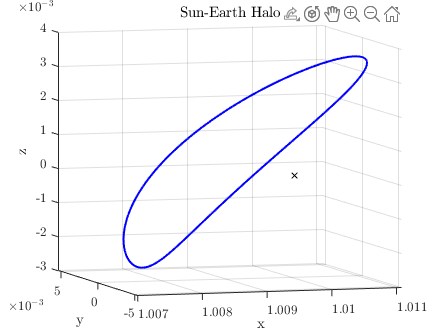

% Find initial conditions
generate_halo;

tspan = 0:60:31449600*15;
IC = x0_lpo;
IC(1:3) = IC(1:3)*param.Lstar;
IC(4:6) = IC(4:6)*param.Vstar;
opts = odeset('RelTol',1e-12,'AbsTol',1e-13);

% Simulate JWST
[t,Xj] = ode45(@(t,X) jwst_orbit(t,X,params),tspan,IC,opts);
x_j  = Xj(:,1);
y_j  = Xj(:,2);
z_j  = Xj(:,3);
vx_j = Xj(:,4);
vy_j = Xj(:,5);
vz_j = Xj(:,6);

% Simulate Earth
if isfile('earth_orbit.mat')
    load('earth_orbit.mat');
else
    [t,Xe] = ode45(@(t,X) earth_orbit(t,X,mu1),tspan,[r12;0;0;0;ve;0],opts);
    save earth_orbit Xe
end
x_e  = Xe(:,1);
y_e  = Xe(:,2);
z_e  = Xe(:,3);
vx_e = Xe(:,4);
vy_e = Xe(:,5);
vz_e = Xe(:,6);

## Plot

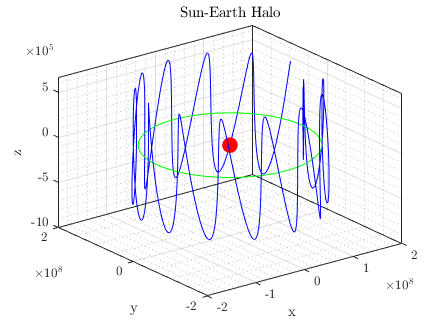

% Plot results 
fig1 = figure(1);
plot3(0,0,0,'.r','MarkerSize',40);
hold on; grid on; grid minor; box on;
plot3(x_j+eta2*r12,y_j,z_j,'-b')
plot3(x_e,y_e,z_e,'-.g')
hold off;

## Animate

% Plot results 
fig2 = figure(2);
plot3(0,0,0,'.r','MarkerSize',40);
hold on;
hh1(1) = line(x_j(1)+eta2*r12,y_j(1),z_j(1),'Marker','.','MarkerSize',20,'Color','b');
hh2(1) = line(r12,0,0,'MarkerSize',40,'Marker','.','Color','g');
hh3(1) = line(x_j(1)+eta2*r12,y_j(1),z_j(1),'LineStyle','-','Color','b');
hh4(1) = line(r12,0,0,'LineStyle','-.','Color','g');

xlabel('x'); ylabel('y'); zlabel('z');
grid on; grid minor; box on;
axis([-2E+08 2E+08 -2E+08 2E+08 -8E+05 8E+05]);
view(3)

tic;     % start timing
for i = 1:100000:length(tspan)
   % Update XData, YData, and ZData
   set(hh1(1),'XData',x_j(i)+eta2*r12,'YData',y_j(i),'ZData',z_j(i));
   set(hh2(1),'XData',x_e(i),'YData',y_e(i),'ZData',z_e(i));
   set(hh3(1),'XData',x_j(1:i)+eta2*r12,'YData',y_j(1:i),'ZData',z_j(1:i));
   set(hh4(1),'XData',x_e(1:i),'YData',y_e(1:i),'ZData',z_e(1:i));
   drawnow;
end
fprintf('Animation (Smart update): %0.2f sec\n', toc);

Animation (Smart update): 51.43 sec


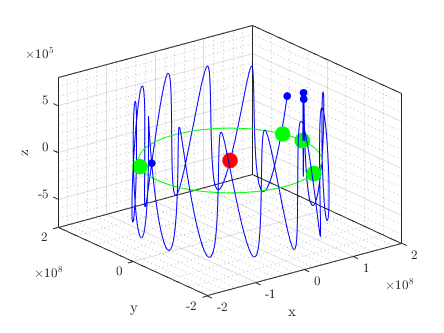

hold off;

## Verification

% Data comparison with Horizons System (Sun - JWST)
sj_data = readmatrix("sun_jwst_rawdata.txt",'Delimiter',',');
sj_data = sj_data(:,3:end);

fig3 = figure(3);
plot3(0,0,0,'.r','MarkerSize',40);
hold on; grid on; grid minor; box on; 
plot3(sj_data(:,1),sj_data(:,2),sj_data(:,3),'-b')
plot3(x_e,y_e,z_e,'-.g')
hold off;

fig5 = figure(5);
plot3(0,0,0,'.r','MarkerSize',40);
hold on;
plot3(x_e,y_e,z_e,'-.g')
hh5(1) = line(sj_data(1,1),sj_data(1,2),sj_data(1,3),'Marker','.','MarkerSize',20,'Color','b');
hh5(2) = line(sj_data(1,1),sj_data(1,2),sj_data(1,3),'LineStyle','-','Color','b');

xlabel('x'); ylabel('y'); zlabel('z');
grid on; grid minor; box on;
axis([-2E+08 2E+08 -2E+08 2E+08 -8E+05 8E+05]);
view(3)

tic;     % start timing
for i = 1:20:length(sj_data(:,1))
   % Update XData, YData, and ZData
   set(hh5(1),'XData',sj_data(i,1),'YData',sj_data(i,2),'ZData',sj_data(i,3));
   set(hh5(2),'XData',sj_data(1:i,1),'YData',sj_data(1:i,2),'ZData',sj_data(1:i,3));
   drawnow;
end
fprintf('Animation (Smart update): %0.2f sec\n', toc);

Animation (Smart update): 13.67 sec


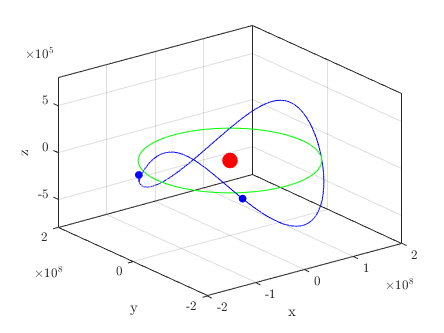

hold off;

% Data comparison with Horizons System (Earth - JWST)
ej_data = readmatrix("earth_jwst_rawdata.txt",'Delimiter',',');
ej_data = ej_data(:,3:end);

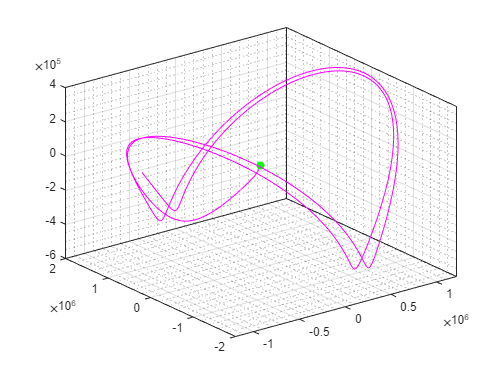

fig4 = figure(4);
plot3(0,0,0,'.g','MarkerSize',20);
hold on; grid on; grid minor; box on; 
plot3(ej_data(:,1),ej_data(:,2),ej_data(:,3),'-m')
hold off;

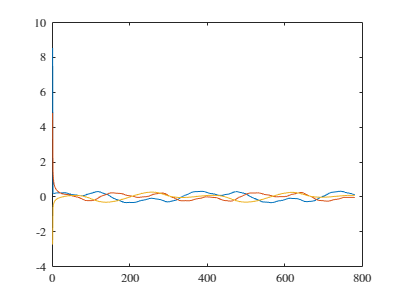

plot(ej_data(:,4))
hold on;
plot(ej_data(:,5))
plot(ej_data(:,6))
hold off;

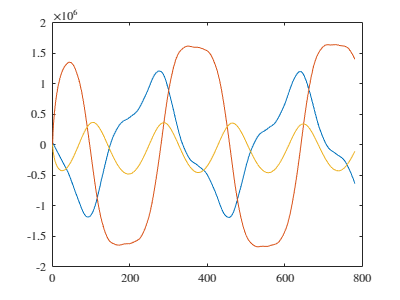

plot(ej_data(:,1))
hold on;
plot(ej_data(:,2))
plot(ej_data(:,3))
hold off;

% Specific orbital energy conservation
En = (vx.^2 + vy.^2) / 2 - mu_e ./ sqrt(x.^2 + y.^2);

fig2 = figure(Renderer="painters");
    plot(t,En,'.r')
    grid on; grid minor; box on; 
    xlabel('$t$')
    ylabel('$\epsilon$')

## Fuctions

function dX = jwst_orbit(t,X,param)
    % Unpack states
    x = X(1); y = X(2); z = X(3);
    vx = X(4); vy = X(5); vz = X(6);
    
    % Unpack parameters
    Omega = param.Omega;
    mu1 = param.mu1;
    mu2 = param.mu2;
    eta1 = param.eta1;
    eta2 = param.eta2;
    r12 = param.r12;
    r23 = param.r23;

    % Distance from Sun and Earth
    r1 = sqrt( (x+eta2*r12)^2 + y^2 + z^2);
    r2 = sqrt( (x-eta1*r12)^2 + y^2 + z^2);
    % r2 = r23;

    % Forces
    Fx = -mu1/r1^3 * (x + eta2*r12) - mu2/r2^3 * (x - eta1*r12);
    Fy = -mu1/r1^3 * y - mu2/r2^3 * y;
    Fz = -mu1/r1^3 * z - mu2/r2^3 * z;

    % Equations of motion
    xdot = vx;
    ydot = vy;
    zdot = vz;
    xddot = 2*Omega*vy + Omega^2*x + Fx;
    yddot = -2*Omega*vx + Omega^2*y + Fy;
    zddot = Fz;

    dX = [xdot;ydot;zdot;xddot;yddot;zddot];
end

function dX = earth_orbit(t,X,mu)
    % Unpack states
    x = X(1); y = X(2); z = X(3);
    vx = X(4); vy = X(5); vz = X(6);
    % Equations of motion
    xdot = vx;
    ydot = vy;
    zdot = vz;
    xddot = -mu * x / (x^2 + y^2)^1.5;
    yddot = -mu * y / (x^2 + y^2)^1.5;
    zddot = 0;
    dX = [xdot; ydot; zdot; xddot; yddot; zddot];
end